# Non-vaccine (SIR)

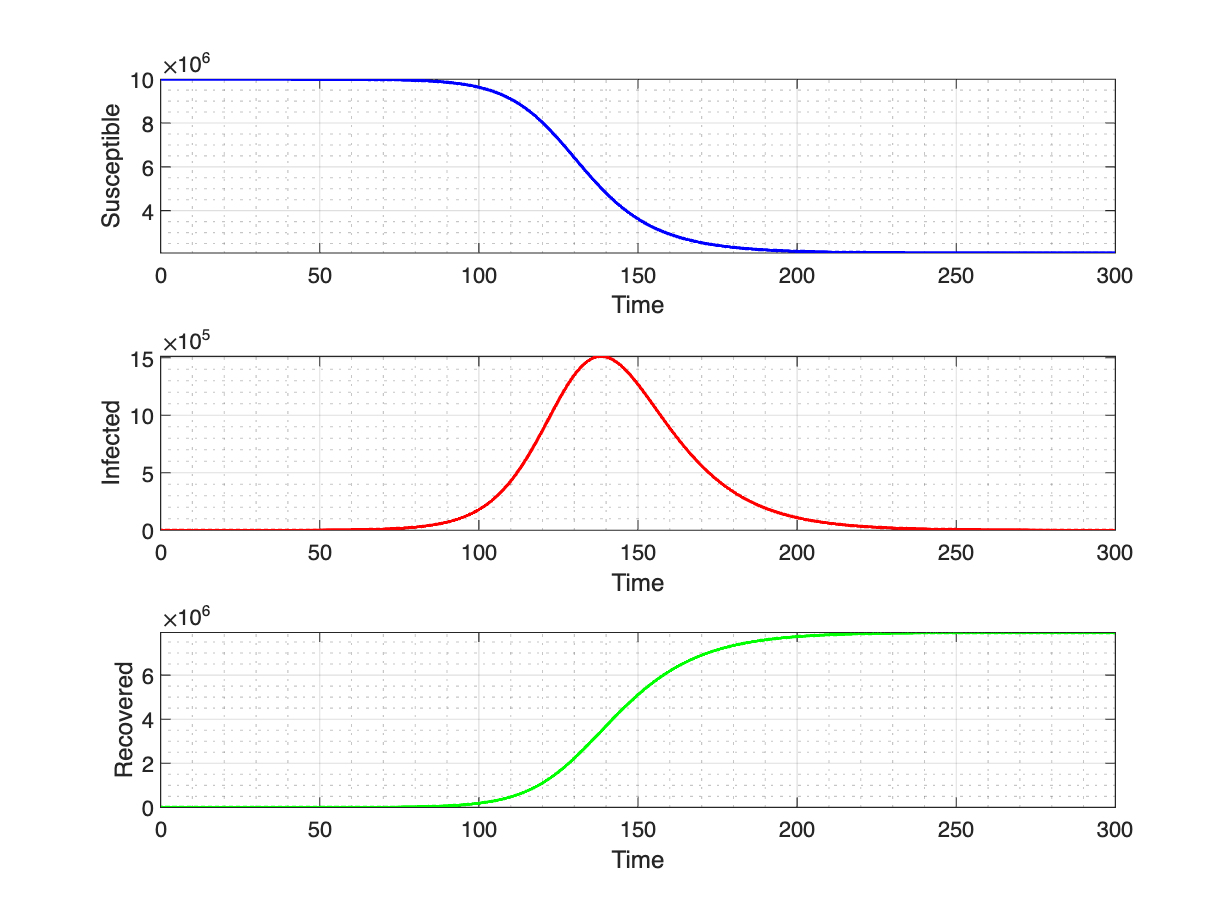

clear all; clc; close all;

% 초기 조건 설정
beta = 0.00000001987 * 1e7;     % 전염율
gamma = 0.1;            % 회복율
N = 1e7;               % 총 인구
I0 = 10;                 % 초기 감염자 수
R0 = 0;                 % 초기 회복자 수
S0 = N - I0 - R0; % 초기 미감염자 수
t_end = 300;    % 시뮬레이션 기간
dt = 0.1;       % 시간 간격

% 초기 조건 설정
S = S0;
I = I0;
R = R0;

% 결과를 저장할 배열 초기화
steps = t_end / dt;
t = zeros(1, steps);
S_array = zeros(1, steps);
I_array = zeros(1, steps);
A_array = zeros(1, steps);


% RK4 시뮬레이션
for i = 1:steps
    t(i) = i * dt;
    
    % RK4를 사용하여 미분 방정식 계산
    [k1_S, k1_I, k1_R] = SIR(S, I, R, beta, gamma, N);
    [k2_S, k2_I, k2_A] = SIR(S + 0.5*dt*k1_S, I + 0.5*dt*k1_I, R + 0.5*dt*k1_R, beta, gamma, N);
    [k3_S, k3_I, k3_A] = SIR(S + 0.5*dt*k2_S, I + 0.5*dt*k2_I, R + 0.5*dt*k2_A, beta, gamma, N);
    [k4_S, k4_I, k4_A] = SIR(S + dt*k3_S, I + dt*k3_I, R + dt*k3_A, beta, gamma, N);
    
    S = S + (dt/6) * (k1_S + 2*k2_S + 2*k3_S + k4_S);
    I = I + (dt/6) * (k1_I + 2*k2_I + 2*k3_I + k4_I);
    R = R + (dt/6) * (k1_R + 2*k2_A + 2*k3_A + k4_A);
    
    % 결과 저장
    S_array(i) = S;
    I_array(i) = I;
    A_array(i) = R;
end

% 결과 그래프 플로팅
figure;

subplot(3,1,1)
plot(t, S_array, 'b', LineWidth=1.5);
xlabel('Time');
ylabel('Susceptible');
grid on; grid minor;

subplot(3,1,2)
plot(t, I_array, 'r', LineWidth=1.5);
xlabel('Time');
ylabel('Infected');
grid on; grid minor;

subplot(3,1,3)
plot(t, A_array, 'g', LineWidth=1.5);
ylabel('Recovered');
xlabel('Time');
grid on; grid minor;

# Vaccine (SIR)

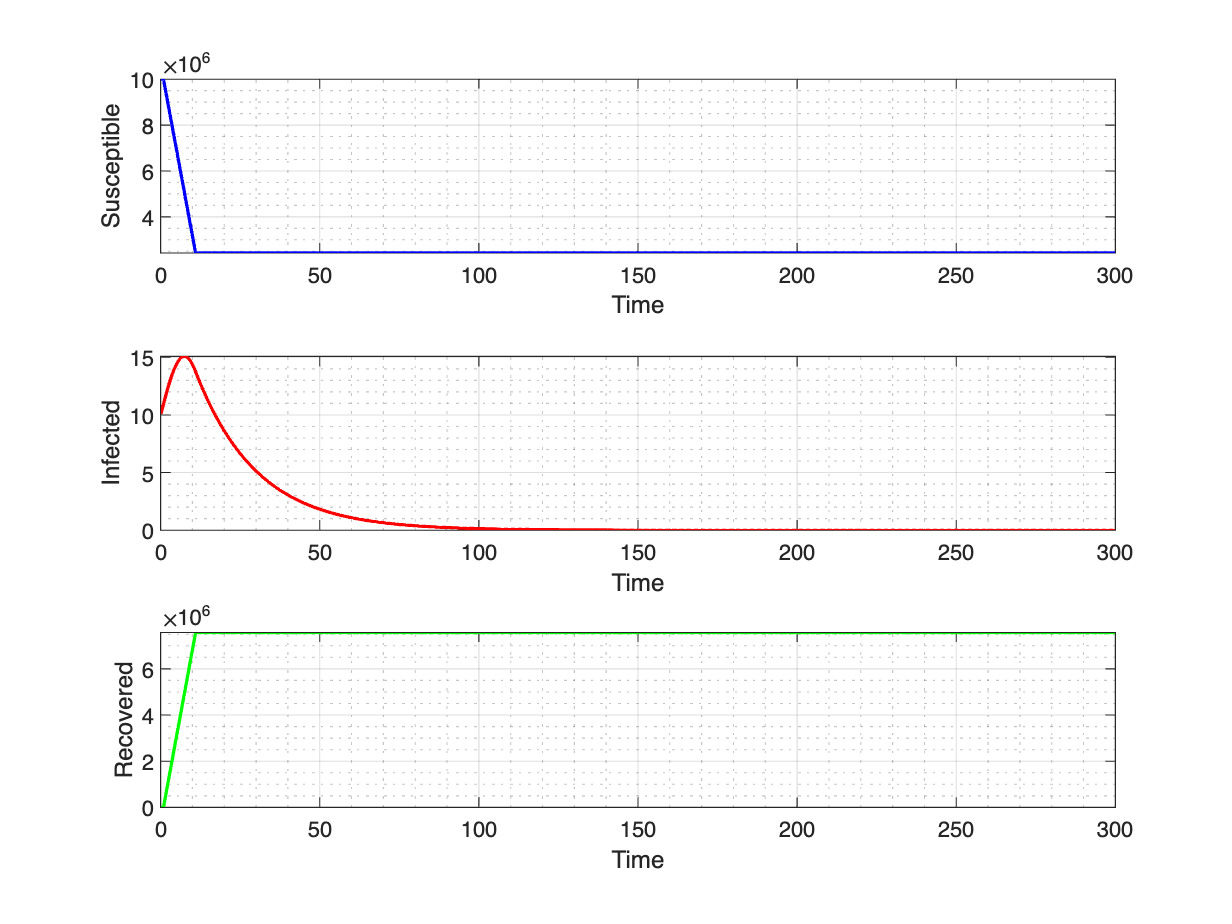

% 초기 조건 설정
beta = 0.00000001987 * 1e7;    
gamma = 0.1;            
N = 1e7;               
I0 = 10;                
R0 = 0;                 
S0 = N - I0 - R0; % 초기 미감염자 수
t_end = 300;    
dt = 0.1;       % 시간 간격

% 초기 조건 설정
S = S0;
I = I0;
R = R0;

% 결과를 저장할 배열 초기화
steps = t_end / dt;
t = zeros(1, steps);
S_array = zeros(1, steps);
I_array = zeros(1, steps);
A_array = zeros(1, steps);

% 백신 접종 시작 및 종료 시간 설정
vaccination_start = 1;  % 백신 접종 시작 시간
vaccination_end = vaccination_start + 10;  % 백신 접종 종료 시간

% RK4 시뮬레이션
for i = 1:steps
    t(i) = i * dt;
    
    % 특정 기간 동안만 백신 접종을 시뮬레이션에 추가
    if t(i) >= vaccination_start && t(i) <= vaccination_end
        vaccinated = min(75000, S); % 매 시간마다 5명씩 백신 접종
        S = S - vaccinated;
        R = R + vaccinated;
    end
    
    % RK4를 사용하여 미분 방정식 계산
    [k1_S, k1_I, k1_R] = SIR(S, I, R, beta, gamma, N);
    [k2_S, k2_I, k2_A] = SIR(S + 0.5*dt*k1_S, I + 0.5*dt*k1_I, R + 0.5*dt*k1_R, beta, gamma, N);
    [k3_S, k3_I, k3_A] = SIR(S + 0.5*dt*k2_S, I + 0.5*dt*k2_I, R + 0.5*dt*k2_A, beta, gamma, N);
    [k4_S, k4_I, k4_A] = SIR(S + dt*k3_S, I + dt*k3_I, R + dt*k3_A, beta, gamma, N);
    
    S = S + (dt/6) * (k1_S + 2*k2_S + 2*k3_S + k4_S);
    I = I + (dt/6) * (k1_I + 2*k2_I + 2*k3_I + k4_I);
    R = R + (dt/6) * (k1_R + 2*k2_A + 2*k3_A + k4_A);
    
    % 결과 저장
    S_array(i) = S;
    I_array(i) = I;
    A_array(i) = R;
end

% 결과 그래프 플로팅
figure;

subplot(3,1,1)
plot(t, S_array, 'b', LineWidth=1.5);
xlabel('Time');
ylabel('Susceptible');
grid on; grid minor;

subplot(3,1,2)
plot(t, I_array, 'r', LineWidth=1.5);
xlabel('Time');
ylabel('Infected');
grid on; grid minor;

subplot(3,1,3)
plot(t, A_array, 'g', LineWidth=1.5);
ylabel('Recovered');
xlabel('Time');
grid on; grid minor;

# NON-Vaccine : SLIAR

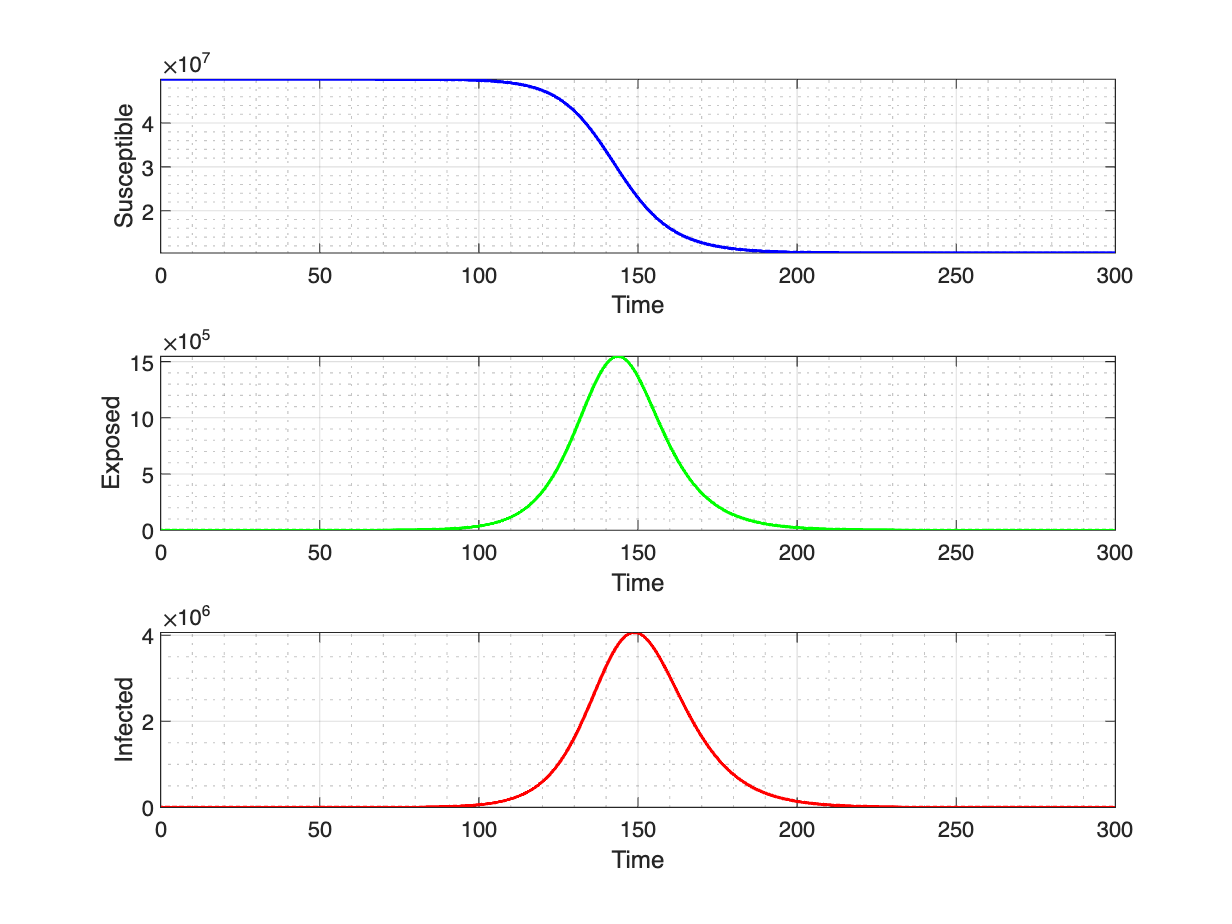

clear all; clc; close all;

% 초기 조건 설정
beta = 1.32339796 * 1e-8;    
psi = 0.7;
nu_daily_max= 750000 ;
nu_total_max= 25000000; 
kappa= 0.7143;
alpha= 0.1667;
tau= 0.0;
p= 0.667;
eta= 0.1667;
f= 0.999;
epsilon= 0.0;
q= 0.5;
delta= 0.5;
S0= 50000000;
E0= 0;
I0= 1;
A0= 0;
t_end = 300;    
dt = 0.1;       % 시간 간격
nu = 0.0;

% 초기 조건 설정
S = S0;
E = E0;
I = I0;
A = A0;

% 결과를 저장할 배열 초기화
steps = t_end / dt;
t = zeros(1, steps);
S_array = zeros(1, steps);
E_array = zeros(1, steps);
I_array = zeros(1, steps);
A_array = zeros(1, steps);

% SEIAR 모델 시뮬레이션
for i = 1:steps
    t(i) = i * dt;

    
    % RK4를 사용하여 미분 방정식 계산
    [k1_S, k1_E, k1_I, k1_A] = SLIAR(S, E, I, A, beta, psi, nu, kappa, alpha, tau, p, eta, f, epsilon, q, delta);
    [k2_S, k2_E, k2_I, k2_A] = SLIAR(S + 0.5*dt*k1_S, E + 0.5*dt*k1_E, I + 0.5*dt*k1_I, A + 0.5*dt*k1_A, beta, psi, nu, kappa, alpha, tau, p, eta, f, epsilon, q, delta);
    [k3_S, k3_E, k3_I, k3_A] = SLIAR(S + 0.5*dt*k2_S, E + 0.5*dt*k2_E, I + 0.5*dt*k2_I, A + 0.5*dt*k2_A, beta, psi, nu, kappa, alpha, tau, p, eta, f, epsilon, q, delta);
    [k4_S, k4_E, k4_I, k4_A] = SLIAR(S + dt*k3_S, E + dt*k3_E, I + dt*k3_I, A + dt*k3_A, beta, psi, nu, kappa, alpha, tau, p, eta, f, epsilon, q, delta);
    
    S = S + (dt/6) * (k1_S + 2*k2_S + 2*k3_S + k4_S);
    E = E + (dt/6) * (k1_E + 2*k2_E + 2*k3_E + k4_E);
    I = I + (dt/6) * (k1_I + 2*k2_I + 2*k3_I + k4_I);
    A = A + (dt/6) * (k1_A + 2*k2_A + 2*k3_A + k4_A);
    
    % 결과 저장
    S_array(i) = S;
    E_array(i) = E;
    I_array(i) = I;
    A_array(i) = A;
end

% 결과 그래프 플로팅
figure;

subplot(3,1,1)
plot(t, S_array, 'b', LineWidth=1.5);
xlabel('Time');
ylabel('Susceptible');
grid on; grid minor;

subplot(3,1,2)
plot(t, E_array, 'g', LineWidth=1.5);
xlabel('Time');
ylabel('Exposed');
grid on; grid minor;

subplot(3,1,3)
plot(t, I_array, 'r', LineWidth=1.5);
ylabel('Infected');
xlabel('Time');
grid on; grid minor;

# Vaccine : SLIAR

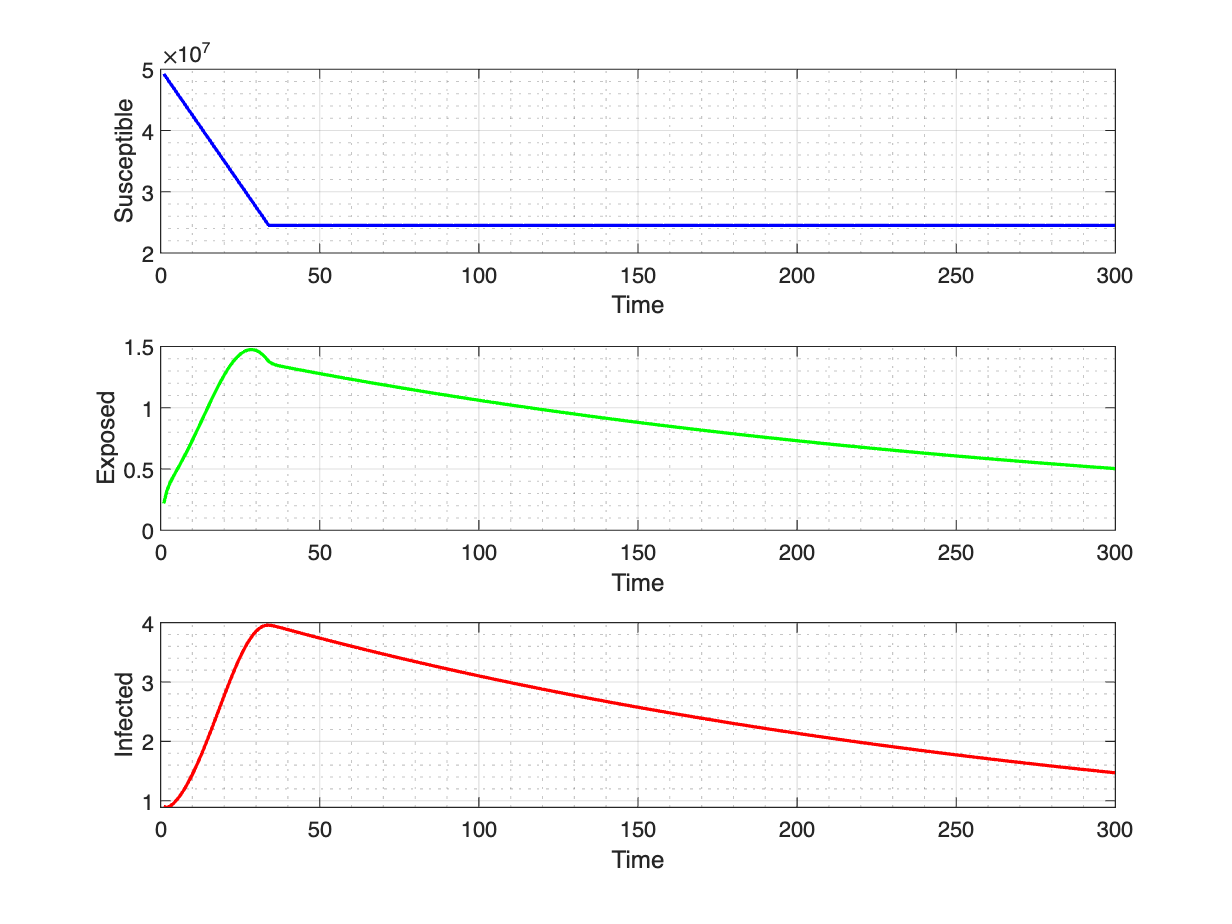

clear all; clc; close all;
% 초기 조건 설정
beta = 1.32339796 * 1e-8;     % 전염율
psi = 0.7;
nu_daily_max= 750000;
nu_total_max= 25000000; 
kappa= 0.7143;
alpha= 0.1667;
tau= 0.0;
p= 0.667;
eta= 0.1667;
f= 0.999;
epsilon= 0.0;
q= 0.5;
delta= 0.5;
S0= 50000000;
E0= 0;
I0= 1;
A0= 0;
t_end = 300;   
dt = 1;       % 시간 간격
nu = 0.0;

% 초기 조건 설정
S = S0;
E = E0;
I = I0;
A = A0;

% 결과를 저장할 배열 초기화
steps = t_end / dt;
t = zeros(1, steps);
S_array = zeros(1, steps);
E_array = zeros(1, steps);
I_array = zeros(1, steps);
A_array = zeros(1, steps);

% 백신 접종 시작 및 종료 시간 설정
vaccination_start = 1;  % 백신 접종 시작 시간
vaccination_end = vaccination_start + 33;  % 백신 접종 종료 시간

% SEIAR 모델 시뮬레이션
for i = 1:steps
    t(i) = i * dt;

    % 특정 기간 동안만 백신 접종을 시뮬레이션에 추가
    if t(i) >= vaccination_start && t(i) <= vaccination_end
        vaccinated = min(nu_daily_max*dt, S);
        S = S - vaccinated;
    end

    
    % RK4를 사용하여 미분 방정식 계산
    [k1_S, k1_E, k1_I, k1_A] = SLIAR(S, E, I, A, beta, psi, nu, kappa, alpha, tau, p, eta, f, epsilon, q, delta);
    [k2_S, k2_E, k2_I, k2_A] = SLIAR(S + 0.5*dt*k1_S, E + 0.5*dt*k1_E, I + 0.5*dt*k1_I, A + 0.5*dt*k1_A, beta, psi, nu, kappa, alpha, tau, p, eta, f, epsilon, q, delta);
    [k3_S, k3_E, k3_I, k3_A] = SLIAR(S + 0.5*dt*k2_S, E + 0.5*dt*k2_E, I + 0.5*dt*k2_I, A + 0.5*dt*k2_A, beta, psi, nu, kappa, alpha, tau, p, eta, f, epsilon, q, delta);
    [k4_S, k4_E, k4_I, k4_A] = SLIAR(S + dt*k3_S, E + dt*k3_E, I + dt*k3_I, A + dt*k3_A, beta, psi, nu, kappa, alpha, tau, p, eta, f, epsilon, q, delta);
    
    S = S + (dt/6) * (k1_S + 2*k2_S + 2*k3_S + k4_S);
    E = E + (dt/6) * (k1_E + 2*k2_E + 2*k3_E + k4_E);
    I = I + (dt/6) * (k1_I + 2*k2_I + 2*k3_I + k4_I);
    A = A + (dt/6) * (k1_A + 2*k2_A + 2*k3_A + k4_A);
    
    % 결과 저장
    S_array(i) = S;
    E_array(i) = E;
    I_array(i) = I;
    A_array(i) = A;
end

% 결과 그래프 플로팅
figure;

subplot(3,1,1)
plot(t, S_array, 'b', LineWidth=1.5);
xlabel('Time');
ylabel('Susceptible');
grid on; grid minor;

subplot(3,1,2)
plot(t, E_array, 'g', LineWidth=1.5);
xlabel('Time');
ylabel('Exposed');
grid on; grid minor;

subplot(3,1,3)
plot(t, I_array, 'r', LineWidth=1.5);
ylabel('Infected');
xlabel('Time');
grid on; grid minor;

function [dS, dE, dI, dA] = SLIAR(S, E, I, A, beta, psi, nu, kappa, alpha, tau, p, eta, f, epsilon, q, delta)
    Lambda = epsilon * E + (1 - q) * I + delta * A;
    % nu*S : the number of vaccination ==> nu * S : nu
    dS = -beta * S * Lambda - psi * nu * S;
    dE = beta * S * Lambda - kappa * E;
    dI = p * kappa * E - alpha * I - tau * I;
    dA = (1 - p) * kappa * E - eta * A;
end



% 미분 방정식 계산 함수
function [dS, dI, dR] = SIR(S, I, R, beta, gamma, N)
    dS = -beta * S * I / N;
    dI = beta * S * I / N - gamma * I;
    dR = gamma * I;
end
